# Lab 1: Quasi-static HEV model and Rule Based Control

## Introduction

In the first lab module, we are going to implement a rule based control logic and couple it to a quasi-static HEV powertrain model. The vehicle model will be provided to you, while developing the control logic is left to you and is the object of the first lab assignement.

But before we delve into that, we will first introduce and inspect the vehicle model and some other important aspects, such as managing the cycle data and the vehicle data. Understanding them will be crucial for all of the lab assignments in this course.

## The fundamental HEV EMS problem

The fundamental goal of designing an* Energy Managment Strategy* is to control the HEV powerflow in order to minimize some cost; in our case, the fuel consumption.

We pose this problem in terms of a discrete time optimal control problem. In an optimal control problem, we have a dynamic system whose state $x$ evolves in time while being influenced by some control variable $u$ which we can act on. The goal is to determine the optimal control sequence that minimizes some incurred cost.

The basic ingredients are:

- the state dynamics    $x_\mathrm{k+1} = f(x_k,u_k,w_k)$,

- a stage cost    $g(x_k,u_k,w_k)
$.

The total cost to be minimized is: $J(x_0,u_1,...,u_{N-1}) = \sum_{k=0}^{N-1} g(x_k,u_k,w_k)$.

Here, the subscript $k$ identifies time intervals and $w_k$, the exogenous inputs, are variables that influence the state dynamics and cost but are independent of the state and control variables.

In these lab sessions, we will study a series hybrid architecture. Our control problem will have one state variable, the battery's SOC, and two control variables, the engine speed and torque:

$x = \sigma$        $$u = [\omega_\text{eng}, T_\mathrm{eng}]$$.

The stage cost is the fuel flow rate and the total cost is therefore the total fuel consumption. The exogenous inputs are the vehicle speed and acceleration profiles.

In terms of our practical implementation, we will use a single function to evaluate the state dynamics and the stage cost, as well as some additional stuff. We will call this function the *vehicle model.*

The vehicle model is used to:

- update the value of the state variable by advancing the simulation one timestep forward,

- evaluate the corresponding fuel consumption,

- (optional) check that the selected control variables are feasible,

- (optional) return additional physical quantities of interest.

By *feasible *control variables, we mean that the selected control varibles do not violate the constraints that we will set on the various powertrain components (for example, that the engine torque does not exceed its limit torque).

## Your goal

In this first lab assignment, your task will be to design a control logic that defines the control variables to be adopted, and then implement it in a simulation framework. The simulation framework will simulate how the HEV behaves in a given driving mission, using your controller. The vehicle model is already provided to you, your task is to set up the simulation framework, design the the control strategy and test it.

Our simulation framework will first load the cycle data and the vehicle data and then run the simulation by looping on time (more precisely, we discretize time in a series of time intervals and loop on the time intervals). For each time interval, you will first use your controller to determine the control variables to be used and then advance the simulation by one timestep using these control variables.

It will look something like this:

You will have to design the *powerflow_controller *function.

## Set up the search path

In order to use the functions contained in the *models*, *data* and utlilties *folders*, we must first add the folders themselves to MATLAB's current path. We can do this programmatically by using `addpath`.

addpath("models");
addpath("data");
addpath("utilities");

## Load the cycle data

We start by loading the driving cycle data. The driving cycle (aka the driving mission) is defined by a speed trace and is provided to you in data/WLTP3.mat.

Let's load the mat-file.

clear
% Load driving cycle data
mis = load(fullfile("data", "WLTP.mat"));

We are loading the contents of the file `WLTP.mat` into a structure called `mis`. If you inspect `mis`, you'll notice we loaded three varaibles: `time_s` and `speed_kmh` and `acceleration_m_s2`. Let's rename them and convert the vehicle speed in SI units.

time = mis.time_s; % s 
vehSpd = mis.speed_km_h ./ 3.6; % m/s
vehAcc = mis.acceleration_m_s2; % m/(s^2)

Let us now inspect our driving cycle:

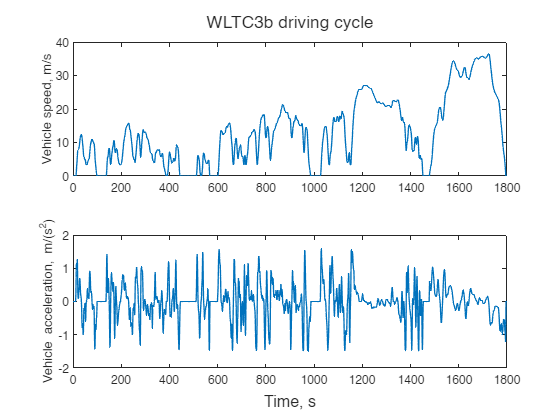

% Create the figure canvas
t = tiledlayout(2,1);

nexttile(1)
% Plot the vehicle speed
plot(time, vehSpd, 'LineWidth', 1);
ylabel("Vehicle speed, m/s")

nexttile(2)
% Plot the vehicle acceleration
plot(time, vehAcc, 'LineWidth', 1);
ylabel("Vehicle acceleration, m/(s^2)")
% Add x-axis label and a title
xlabel(t, "Time, s")
title(t, "WLTC3b driving cycle")

## Load the vehicle data

The vehicle data is provided to you in data/vehData.mat. The mat-file contains 7 structures: one for the vehicle mass and rolling resistance coefficients (`body`) and 6 for the powertrain components. In addition, it contains a number `dt` which defines the simulation timestep to be used. Make sure this timestep coincides with the mission timestep (i.e. the timestep specified by mis.time_s).

Let us load the vehicle data.

% Load vehicle data
veh = load(fullfile("data", "vehData.mat"));

Each structure contains simple parameters (numeric scalars) or 1-D characteristics and 2-D maps (interpolants).

This structure will be passed as input to the vehicle model. Also, you might need to pass one or more of these component structures as inputs to your controllers.

For your assignment, you will also be required to scale the vehicle data. The scaling is done with respect to the motor and engine rated powers and the battery nominal energy, which will be unique for each group. To do the actual scaling, use the following function, specifying the design parameters as the last three inputs. Make sure you specify the motor and engine rated powers in Watts and the battery capacity in Watt-hours.

veh = scaleVehData(veh, 70e3, 56e3, 1050);

### A note on interpolants

Consider for example the engine data in `eng`. We have several `griddedInterpolant` objects. These objects store gridded data and easily allow you to evaulate quantities that do not lie on the grid by interpolation. For example, the `maxTrq` interpolant defines the engine limit torque curve as a function of its speed, while fuelMap defines the fuel mass flow rate as a function of the engine speed and torque:


$$T_\mathrm{eng,max} = T_\mathrm{eng,max}(\omega_\mathrm{eng})$$



$$\dot{m}_\mathrm{f} = \dot{m}_\mathrm{f}(\omega_\mathrm{eng}, T_\mathrm{eng})$$


The syntaxes for evaluating the limit torque at any 100 rad/s and the fuel consumption and 100 rad/s and 80 Nm are simply:

veh.eng.maxTrq(100) % Nm

ans = 68.1545

veh.eng.fuelMap(100, 80) % g/s

ans = 0.6161

If you want to access the gridded data (e.g. to draw plots), you can access the independent variables from `[interpolant].GridVectors` and the dependent variables from `[interpolant].Values`. For example:

% Extract engine limit torque data
spdBrk = veh.eng.maxTrq.GridVectors{1}; % Speed breakpoints
maxTrqValues = veh.eng.maxTrq.Values; % Corresponding limit torque

% Extract fuel consumption data
spdBrk = veh.eng.fuelMap.GridVectors{1}; % Speed breakpoints
trqBrk = veh.eng.fuelMap.GridVectors{2}; % Torque breakpoints
fuelFlwRateValues = veh.eng.fuelMap.Values; % Corresponding fuel flow rate

## The simulation loop

% Add models folder to the search path
addpath("models")

% Initialize SOC and engine state
x(1) = 0.6;
engState(1) = 0;

for n = 1:length(time)
    [engSpd(n), engTrq(n)] = thermostatControl(SOC(n), engState(n), vehSpd(n), vehAcc(n), veh);
    [x(n+1), stageCost, unfeas, prof(n)] = hev_model(x(n), [engSpd(n), engTrq(n)], [vehSpd(n), vehAcc(n)], veh);
    engState(n+1) = engTrq(n) > 0;
end

## Post-processing: main results

Let's inspect the function signature for `hev_model:`

function [x_next, stageCost, unfeas, prof] = hev_model(x, u, w, veh)
    ...
end

The function `hev_model` returns additional physical signals starting within the fourth output, `prof`. This is returned as a [scalar structure](https://www.mathworks.com/help/matlab/structures.html). In the simulation loop, we return this output and store it into `prof(n).` Essentially, we are trying to "stack" multiple `prof` structures. What we get is a [nonscalar structure](https://www.mathworks.com/help/matlab/matlab_prog/access-multiple-elements-of-a-nonscalar-struct-array.html), which is a bit inconvenient to work with if you are not practical with MATLAB.

You can use the function `structArray2struct` to transform them into scalar structures containing `Nx1` arrays (N being the cycle length).

% Transform the non-scalar struct containing time profiles into a scalar
% struct; this makes its manipulation easier.
prof = structArray2struct(prof);

We can now more easily manipulate and inspect our results.

### Evaluate fuel economy 

We now want to evaluate our controller design. The two most important metrics we are going to look at are the fuel economy and the final state of charge.

First, let us calculate the total mass of fuel burnt by integrating (using [`trapz`](https://www.mathworks.com/help/matlab/ref/trapz.html)) the fuel flow rate over time for the whole mission:

fuelConsumption = sum(prof.fuelFlwRate).*1e-3; % kg

Then, we can evaluate the fuel economy in l/100km by first converting the fuel consumption to liters and then dividing by the mission length: 

dist = trapz(time, vehSpd) * 1e-3; % km
fuelEconomy = fuelConsumption / veh.eng.fuelDensity / dist * 1e2; % l/100km

We are considering a fuel density of 0.785 kg/l as the engine you are simulating is a gasoline engine.

Next, let's use [fprintf](https://www.mathworks.com/help/matlab/ref/fprintf.html) to display our results:

% Print fuel consumption, fuel economy and final SOC
finalSOC = prof.battSOC(end);
fprintf("Fuel consumption: %.2f kg\n", fuelConsumption);
fprintf("Fuel economy: %.2f l/100km\n", fuelEconomy );
fprintf("Final SOC: %.3f\n", finalSOC );

### Save some results

For your lab assignment, we will ask you to upload your results. Use `save` to store the time profiles, fuel consumption, fuel economy and the final state of charge in a file named *results.mat*.

save("results.mat", "prof", "fuelConsumption", "fuelEconomy", "finalSOC")

## Post-processing: plots and analysis

### Analyzing time profiles

One very important part of your assignment is to analyze the behavior of your controller, to understand the effectiveness of the implemented control logic. For example, we might want to plot the time profile for the battery state of charge.

% Create new figure
figure
% Create the figure canvas
t = tiledlayout(2,1);

nexttile(1)
% Plot the vehicle speed
plot(time, vehSpd, 'LineWidth', 1);
% Add axis labels
xlabel("Time, s")
ylabel("Vehicle speed, m/s")

nexttile(2)
% Plot the vehicle acceleration
plot(time, prof.battSOC, 'LineWidth', 1);
% Add axis labels
xlabel("Time, s")
ylabel("Battery SOC, -")

For your convenience, we also provide you four visualization functions:

- `mainProfiles`: plots time profiles for vehicle speed, SOC, gear number, engine torque-split factor and cumulative fuel consumption.

- `powerProfiles`: plots time profiles for vehicle speed and components power.

- `engMapWithPF`: plots the engine map and the operating points throughout the simulation.

- `emMapWithPF`: plots the e-machine map and the operating points throughout the simulation.

These are contained in the *utilities* folder.

% Add post-processing utilities folder to the search path
addpath("utilities")

All these functions require as input a structure containing all time profiles (`prof`).

### Time profiles

First, let's use `mainProfiles` to inspect the SOC, control signals and fuel consumption over time:

mainProfiles(prof);

Next, let's use `powerProfiles` to inspect the power provided by the various components:

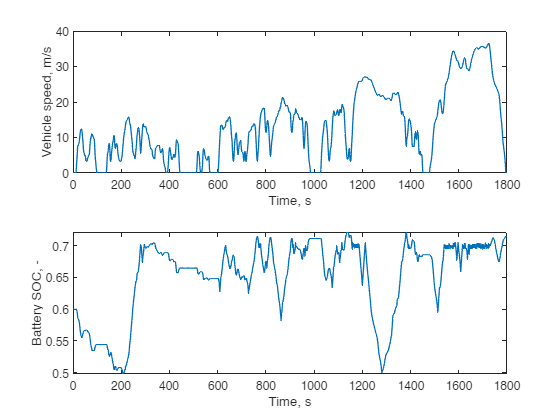

powerProfiles(prof);

### Engine map

We can plot the engine map and overlay the engine operating points using `engMapWithPF`. The third argument can be used to switch from fuel flow rate, break specific fuel consumption and fuel conversion efficiency.

engMapWithPF(veh.eng, prof, 'bsfc');

### Generator map

Similarly, we can plot the generator map and overlay its operating points using `emMapWithPF`. Note how we use the `'gen'` option as a third argument to specify that this component is a generator (and not a motor).

emMapWithPF(veh.gen, prof, 'gen');

### Motor map

Finally, we can plot the motor map and overlay its operating points using `emMapWithPF`.

emMapWithPF(veh.mot, prof, 'mot');